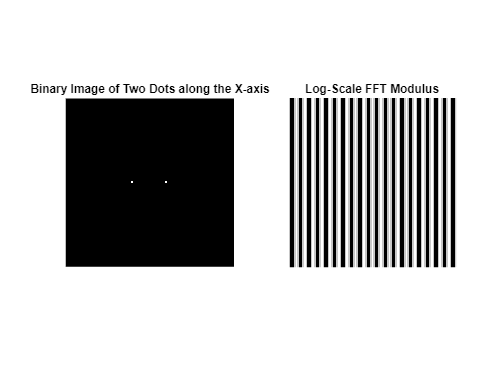

% ACTIVITY 2.2.3 CONVOLUTION THEOREM REDUX
%Binary image of two dots
image = zeros(100);
dot_x = 50;  % x-coordinate of the dots
dot_y = 50;  % y-coordinate of the dots
dot_distance = 10;  % distance between the dots
image(dot_y, dot_x - dot_distance) = 1;
image(dot_y, dot_x + dot_distance) = 1;

%FFT
fft_result = fftshift(fft2(image));
fft_modulus = abs(fft_result);
fft_log = log(fft_modulus + 1);

% Display the binary image and its log-scale FFT modulus
figure;
subplot(1, 2, 1); imshow(image); title('Binary Image of Two Dots along the X-axis'); 
subplot(1, 2, 2); imagesc(fft_log); axis square; title('Log-Scale FFT Modulus'); axis off;
colormap gray;

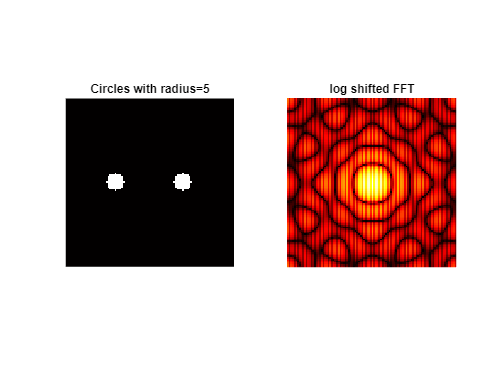

%Circles with radius of 5
image = zeros(100);
radius = 5;
[X, Y] = meshgrid(1:size(image, 2), 1:size(image, 1));
circle1 = ((X - 30).^2 + (Y - 50).^2) <= radius.^2;
circle2 = ((X - 70).^2 + (Y - 50).^2) <= radius.^2;
image(circle1 | circle2) = 1;

%FFT
fft_result = fftshift(fft2(image));
fft_modulus = abs(fft_result);
fft_modulus_log = log(fft_modulus + 1);


% Display the image and its FT modulus
figure;
subplot(1, 2, 1); imshow(image); title('Circles with radius=5');
subplot(1, 2, 2); imagesc(fft_modulus_log); axis square; title('log shifted FFT'); axis off;
colormap hot;

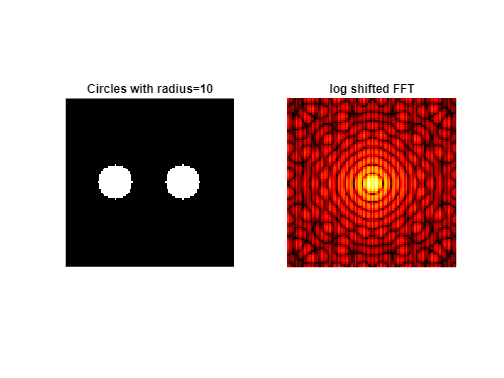

%Circles with radius of 10
image = zeros(100);
radius = 10;
[X, Y] = meshgrid(1:size(image, 2), 1:size(image, 1));
circle1 = ((X - 30).^2 + (Y - 50).^2) <= radius.^2;
circle2 = ((X - 70).^2 + (Y - 50).^2) <= radius.^2;
image(circle1 | circle2) = 1;

%FFT
fft_result = fftshift(fft2(image));
fft_modulus = abs(fft_result);
fft_modulus_log = log(fft_modulus + 1);


% Display the image and its FT modulus
figure;
subplot(1, 2, 1); imshow(image); title('Circles with radius=10');
subplot(1, 2, 2); imagesc(fft_modulus_log); axis square; title('log shifted FFT'); axis off;
colormap hot;

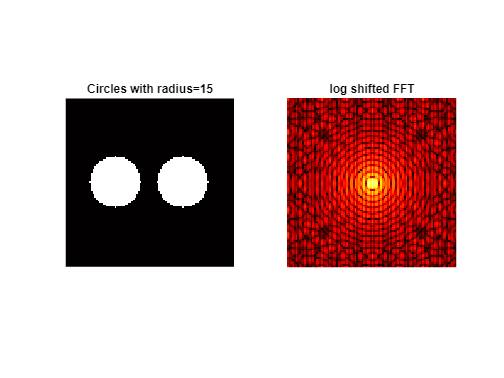

%Circles with radius of 15
image = zeros(100);
radius = 15;
[X, Y] = meshgrid(1:size(image, 2), 1:size(image, 1));
circle1 = ((X - 30).^2 + (Y - 50).^2) <= radius.^2;
circle2 = ((X - 70).^2 + (Y - 50).^2) <= radius.^2;
image(circle1 | circle2) = 1;

%FFT
fft_result = fftshift(fft2(image));
fft_modulus = abs(fft_result);
fft_modulus_log = log(fft_modulus + 1);


% Display the image and its FT modulus
figure;
subplot(1, 2, 1); imshow(image); title('Circles with radius=15');
subplot(1, 2, 2); imagesc(fft_modulus_log); axis square; title('log shifted FFT');  axis off;
colormap hot;

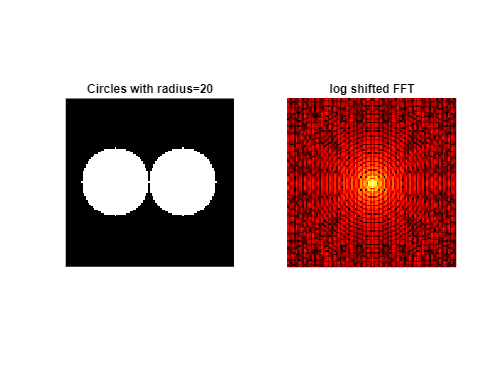

%Circles with radius of 20
image = zeros(100);
radius = 20;
[X, Y] = meshgrid(1:size(image, 2), 1:size(image, 1));
circle1 = ((X - 30).^2 + (Y - 50).^2) <= radius.^2;
circle2 = ((X - 70).^2 + (Y - 50).^2) <= radius.^2;
image(circle1 | circle2) = 1;

%FFT
fft_result = fftshift(fft2(image));
fft_modulus = abs(fft_result);
fft_modulus_log = log(fft_modulus + 1);


% Display the image and its FT modulus
figure;
subplot(1, 2, 1); imshow(image); title('Circles with radius=20');
subplot(1, 2, 2); imagesc(fft_modulus_log); axis square; title('log shifted FFT'); axis off;
colormap hot;

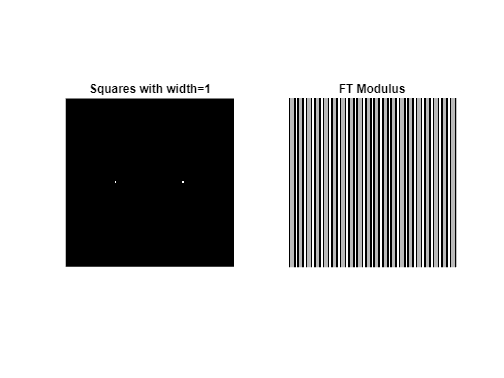

%Square with width of 1
image = zeros(100);
width = 1;
[X, Y] = meshgrid(1:size(image, 2), 1:size(image, 1));
square1 = abs(X - 30) <= width/2 & abs(Y - 50) <= width/2;
square2 = abs(X - 70) <= width/2 & abs(Y - 50) <= width/2;
image(square1 | square2) = 1;

%FFT
fft_result = fftshift(fft2(image));
fft_modulus = abs(fft_result);
fft_modulus_log = log(fft_modulus + 1);

% Display the image and its FT modulus
figure;
subplot(1, 2, 1); imshow(image); title('Squares with width=1');
subplot(1, 2, 2); imagesc(fft_modulus); axis square; title('FT Modulus'); axis off;
colormap gray;

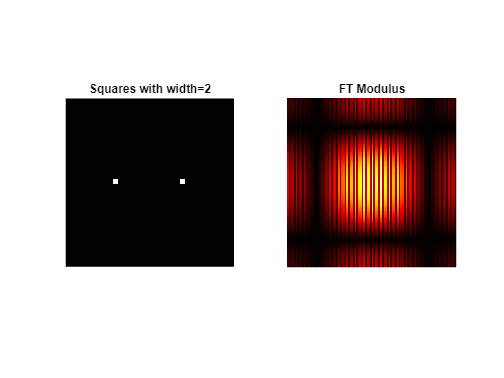


%Square with width of 2
image = zeros(100);
width = 2;
[X, Y] = meshgrid(1:size(image, 2), 1:size(image, 1));
square1 = abs(X - 30) <= width/2 & abs(Y - 50) <= width/2;
square2 = abs(X - 70) <= width/2 & abs(Y - 50) <= width/2;
image(square1 | square2) = 1;

%FFT
fft_result = fftshift(fft2(image));
fft_modulus = abs(fft_result);
fft_modulus_log = log(fft_modulus + 1);

% Display the image and its FT modulus
figure;
subplot(1, 2, 1); imshow(image); title('Squares with width=2');
subplot(1, 2, 2); imagesc(fft_modulus); axis square; title('FT Modulus'); axis off;
colormap hot;

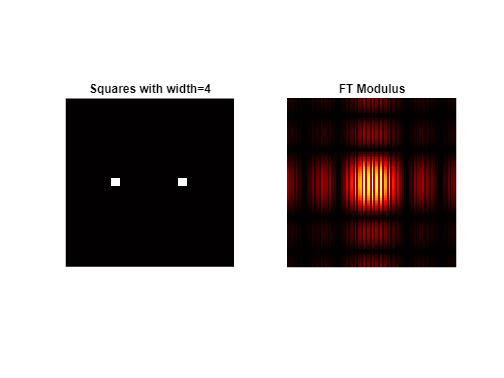

%Square with width of 4
image = zeros(100);
width = 4;
[X, Y] = meshgrid(1:size(image, 2), 1:size(image, 1));
square1 = abs(X - 30) <= width/2 & abs(Y - 50) <= width/2;
square2 = abs(X - 70) <= width/2 & abs(Y - 50) <= width/2;
image(square1 | square2) = 1;

%FFT
fft_result = fftshift(fft2(image));
fft_modulus = abs(fft_result);
fft_modulus_log = log(fft_modulus + 1);

% Display the image and its FT modulus
figure;
subplot(1, 2, 1); imshow(image); title('Squares with width=4');
subplot(1, 2, 2); imagesc(fft_modulus); axis square; title('FT Modulus'); axis off;
colormap hot;

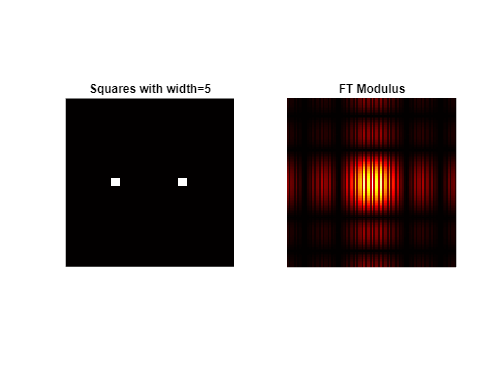

%Square with width of 5
image = zeros(100);
width = 5;
[X, Y] = meshgrid(1:size(image, 2), 1:size(image, 1));
square1 = abs(X - 30) <= width/2 & abs(Y - 50) <= width/2;
square2 = abs(X - 70) <= width/2 & abs(Y - 50) <= width/2;
image(square1 | square2) = 1;

%FFT
fft_result = fftshift(fft2(image));
fft_modulus = abs(fft_result);
fft_modulus_log = log(fft_modulus + 1);

% Display the image and its FT modulus
figure;
subplot(1, 2, 1); imshow(image); title('Squares with width=5');
subplot(1, 2, 2); imagesc(fft_modulus); axis square; title('FT Modulus'); axis off;
colormap hot;

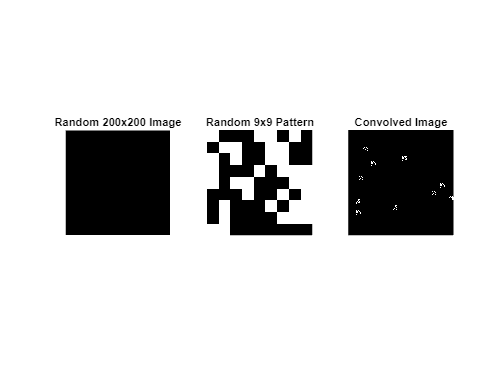

%200x200 array of zeros
A = zeros(200);
rndm = randi([1, 200], 10, 2);      % Generate 10 random coordinates
A(sub2ind(size(A), rndm(:, 1), rndm(:, 2))) = 1;    % Place ones at the random coordinates

%random 9x9 pattern
d = randi([0, 1], 9, 9);

% Convolve A and d
convolved = conv2(A, d);

% Display the results
figure;
subplot(1, 3, 1); imshow(A); title('Random 200x200 Image');
subplot(1, 3, 2); imshow(d); axis off; axis image; title('Random 9x9 Pattern');
subplot(1, 3, 3); imshow(convolved); title('Convolved Image');

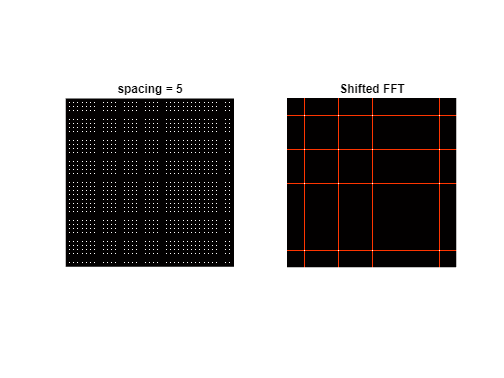

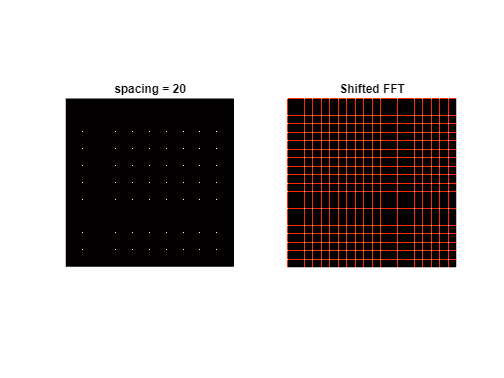

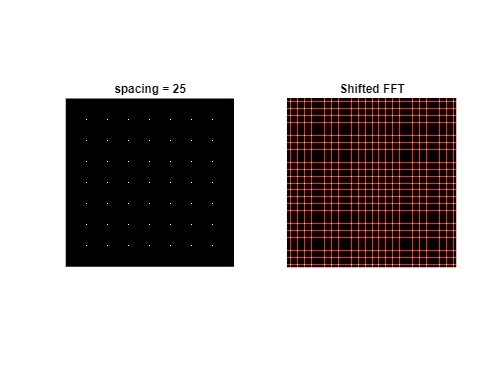

spacing = [5, 20, 25];
spacing2 = [15, 30, 45];

for i = 1:numel(spacing)
    A = zeros(200); [row, column] = size(A);
    j = spacing(i):spacing(i):row - spacing(i);
    k = spacing(i):spacing(i):column - spacing(i);
            A(j,k) = 1;
    fft_a = fft2(A);
    fft_shifted = abs(fftshift(fft_a));
    conv = rescale(log(abs(fft_shifted + 1)),0,256);

    figure;
    subplot(1, 2, 1); imshow(A); title(['spacing = ', num2str(spacing(i))]);
    subplot(1, 2, 2); imagesc(conv); axis off; axis image; title('Shifted FFT');
    colormap hot;
end